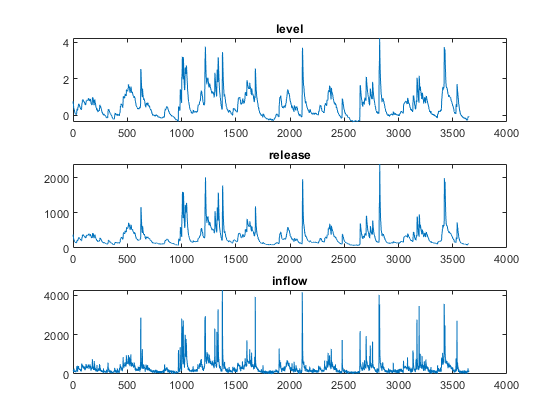

data = load("data\VerbanoTraj.txt");
lake_level = data(:,1);
lake_release = data(:,2);
lake_inflow = data(:,3);

figure;
subplot(3,1,1); plot(lake_level); title('level');
subplot(3,1,2); plot(lake_release); title('release');
subplot(3,1,3); plot(lake_inflow); title('inflow');

## Water supply

### Reliability

w = 100; % Water demand
I_rel = sum(lake_release >= w) / length(lake_release)

I_rel = 0.9477

### Vulnerability (1)

deficit = max( w - lake_release , 0);
I_vul = sum(deficit) / sum(lake_release < w)

I_vul = 11.9227

### Vulnerability (2)

n = 2; % Risk aversion factor
I_def = mean(deficit.^n)

I_def = 10.1318

### Resilience

num = 0;
for i=1:length(lake_release)-1
    if(lake_release(i) < w && lake_release(i+1) >= w)
        num = num + 1;
    end
end
I_res = num / sum(lake_release < w)

I_res = 0.0524

## Flood Control

Ny = length(lake_level) / 365; % Number of years

### Flooding (1)

h_bar =  1.73; % Flooding thereshold
I_f1 = sum(lake_level > h_bar) / Ny

I_f1 = 20.1000

### Flooding (2)

p3 = 0.081;
p2 = -0.483;
p1 = 1.506;
p0 = -1.578;
ht = lake_level;
idx = find( ht > h_bar );
S(idx) = p3*ht(idx).^3 + p2*ht(idx).^2 + p1*ht(idx) + p0;
I_f2 = max(S)

I_f2 = 2.2627

## Environment

% Define percentiles
LP = prctile ( lake_inflow , 25)

LP = 143.6000

HP = prctile ( lake_inflow , 75)

HP = 388.8000

### Environment (1 - 2) Inflow

I_E1 = sum ( lake_inflow < LP) / Ny

I_E1 = 91

I_E2 = sum ( lake_inflow > HP) / Ny

I_E2 = 91.2000

### Environment (1 - 2)  Release

I_E1 = sum ( lake_release < LP) / Ny

I_E1 = 70.9000

I_E2 = sum ( lake_release > HP) / Ny

I_E2 = 96.3000